% SET OPTIONS
importLogs = true;
rtRounding = 10;

%File directories
%Traj-0004:
imgFolder = fullfile('.', '/QuadSimEnv/Results/Traj-0005/fps_20_1');
logFile = fullfile('.','/QuadSimEnv/Results/Traj-0005/fps_20_1/simout.mat');


% INITIALISE CONSTANTS

%INITIALISE WORLD MAP
map = load('./Resources/map.mat');

%Camera variables
%K = [1274.58238813250 0 627.693937913345; 0 1273.36371905619 405.441250468717; 0 0 1]; %23 mm calibration
%K=   [605.8071 0 316.6903; 0 608.4646 256.6409; 0 0 1.0000]; %31 mm calib
K = [1107 0 960; 0 1107 540; 0 0 1]; %virtual camera

%Checkerboard variables
X_pnts_W = map.worldObjectStruct.checkers.Corners/1000; %in m
checkerSize = map.worldObjectStruct.checkers.NumSquares;
checkerEdgeLength = map.worldObjectStruct.checkers.SquareSize; %mm
checker_w_mm = 31*checkerSize(2);
checker_h_mm = 31*checkerSize(1);

%Known coordinate transformations (mapping)
R_unreal2World = [1 0 0; 0 -1 0; 0 0 1];

%other variables
p3pResult = struct();
inlierThreshold = 0.5;


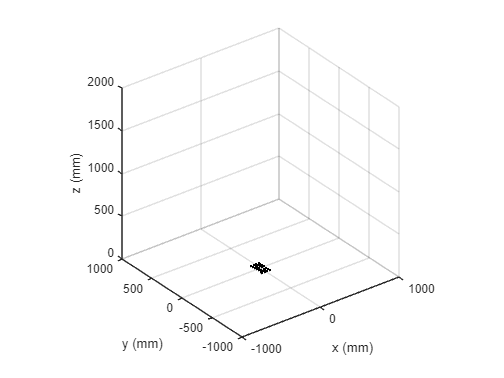

%INTIALISE PLOT
close all

%ADD TRAJECTORIES
plotStruct = initPlots('KneipN', 'Verification', 'EKF');
p3pPlotting.addCheckerboard(plotStruct.traj.Ax, X_pnts_W);

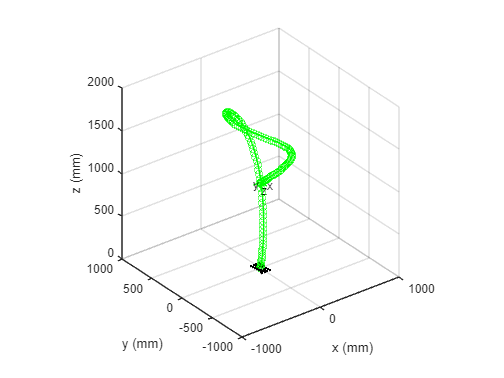

%IMPORT & PLOT LOGGED DATA
if importLogs ==true
    [cam_rtHist_GT, cam_timeHist_GT, cam_stateHist_GT, imuHist] = imgFuncs.importSimLog(logFile,  R_unreal2World);
    lineObj_Ver = plotStruct.traj.plotLines.Verification.line;
    axTextArr_Ver=plotStruct.traj.plotLines.Verification.frameText;
    axLineArr_Ver = plotStruct.traj.plotLines.Verification.frameLines;
    p3pPlotting.updateTraj(lineObj_Ver, axTextArr_Ver, axLineArr_Ver, cam_rtHist_GT);
end

%IMPORT IMAGES
[I_seq, I_seq_times] = imgFuncs.importImageSeq(imgFolder);

Working on frame 1
Working on frame 2
Working on frame 3


Discarding frame 3


Working on frame 4
Working on frame 5
Working on frame 6
Working on frame 7
Working on frame 8
Working on frame 9
Working on frame 10
Working on frame 11
Working on frame 12
Working on frame 13
Working on frame 14
Working on frame 15


Discarding frame 15


Working on frame 16
Working on frame 17
Working on frame 18
Working on frame 19


Discarding frame 19


Working on frame 20
Working on frame 21
Working on frame 22


Discarding frame 22


Working on frame 23
Working on frame 24
Working on frame 25
Working on frame 26
Working on frame 27


Discarding frame 27


Working on frame 28
Working on frame 29
Working on frame 30
Working on frame 31


Discarding frame 31


Working on frame 32
Working on frame 33
Working on frame 34
Working on frame 35
Working on frame 36
Working on frame 37
Working on frame 38
Working on frame 39
Working on frame 40
Working on frame 41
Working on frame 42
Working on frame 43
Working on frame 44
Working on frame 45
Working on frame 46
Working on frame 47
Working on frame 48
Working on frame 49
Working on frame 50
Working on frame 51
Working on frame 52
Working on frame 53
Working on frame 54
Working on frame 55
Working on frame 56
Working on frame 57
Working on frame 58


Discarding frame 58


Working on frame 59


Discarding frame 59


Working on frame 60


Discarding frame 60


Working on frame 61


Discarding frame 61


Working on frame 62


Discarding frame 62


Working on frame 63


Discarding frame 63


Working on frame 64
Working on frame 65
Working on frame 66
Working on frame 67
Working on frame 68
Working on frame 69
Working on frame 70
Working on frame 71
Working on frame 72
Working on frame 73
Working on frame 74
Working on frame 75
Working on frame 76
Working on frame 77
Working on frame 78
Working on frame 79
Working on frame 80
Working on frame 81
Working on frame 82
Working on frame 83
Working on frame 84
Working on frame 85
Working on frame 86
Working on frame 87
Working on frame 88
Working on frame 89
Working on frame 90
Working on frame 91
Working on frame 92
Working on frame 93
Working on frame 94
Working on frame 95
Working on frame 96
Working on frame 97
Working on frame 98
Working on frame 99
Working on frame 100
Working on frame 101
Working on frame 102
Working on frame 103
Working on frame 104
Working on frame 105
Working on frame 106
Working on frame 107
Working on frame 108
Working on frame 109
Working on frame 110
Working on frame 111
Working on frame 112
Working

Discarding frame 113


Working on frame 114
Working on frame 115
Working on frame 116
Working on frame 117
Working on frame 118
Working on frame 119
Working on frame 120
Working on frame 121
Working on frame 122
Working on frame 123
Working on frame 124
Working on frame 125
Working on frame 126
Working on frame 127
Working on frame 128
Working on frame 129
Working on frame 130
Working on frame 131
Working on frame 132
Working on frame 133
Working on frame 134
Working on frame 135
Working on frame 136
Working on frame 137
Working on frame 138


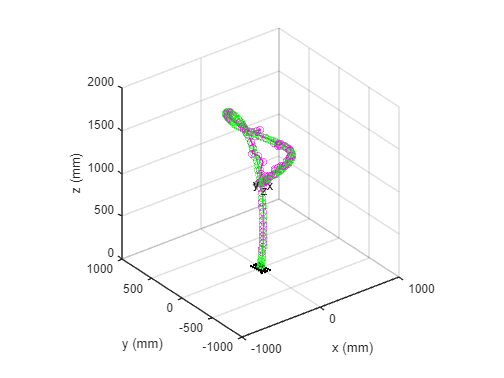

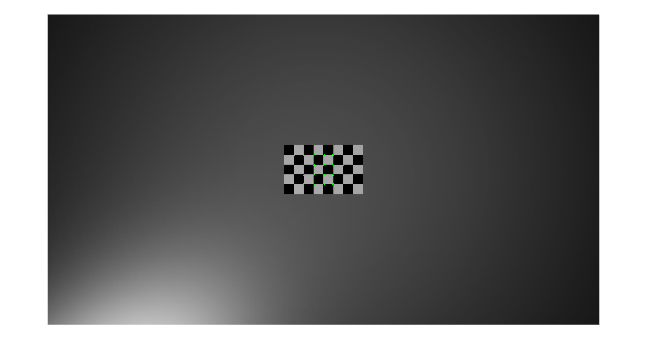

%RUN AND PLOT P3P FOR EACH CHECKERBOARD IMAGE
goodFrameCounter = 0;
for i=1:size(I_seq,3)

    disp(strcat("Working on frame ", string(i)));
    
    %Get current frame
    I=I_seq(:,:,i);
    imageArrSize = size(I);
    imageSize=imageArrSize(1:2);

    %Find checkerboard corners
    [x_pnts_i, checkerSize_detected] = detectCheckerboardPoints(I);
    x_pnts_i = transpose(x_pnts_i);    

    %discard any frames where too few corners have been detected
    if (checkerSize_detected(1) ~= checkerSize(1)) || (checkerSize_detected(2) ~= checkerSize(2))
        disp(strcat("Discarding frame ", string(i)));
        continue
    end
    %Otherwise, continue:
    goodFrameCounter = goodFrameCounter +1;
    %Extract useful information
    time_I = I_seq_times(:,i); %time associated with frame
    [~,closestIndex] = min(abs(cam_timeHist_GT-time_I));
    if goodFrameCounter == 1
        startIndex =closestIndex;
    end
    Rt_log_i = cam_rtHist_GT(:,:,closestIndex);


    %Run P3P
    p3pResult = runP3P(p3pResult, time_I, x_pnts_i, X_pnts_W, K, imageSize, checkerSize, inlierThreshold, rtRounding,  'KneipN', 'Matlab');
    plotStruct.traj = updatePlot(plotStruct.traj, p3pResult);


    %Calculate error
    if importLogs == true
        p3pResult = calcRtError(p3pResult, cam_rtHist_GT, cam_timeHist_GT);    
    end

    %Display checkerboard image for this iteration - for troubleshooting
    if (checkerSize_detected(1) <= checkerSize(1)) || (checkerSize_detected(2) <= checkerSize(1)) 
        if i==1
            checkerFig = figure();
            checkerAx = axes('Parent', checkerFig);
            checkerImg = imshow(imgFuncs.markDetectedCheckers(I, x_pnts_i), 'Parent', checkerAx);
        else
            checkerImg.CData = (imgFuncs.markDetectedCheckers(I, x_pnts_i));
            drawnow;
        end 
    end

 end

 
 save(fullfile('.', '/Results/', "p3pResult"));
 



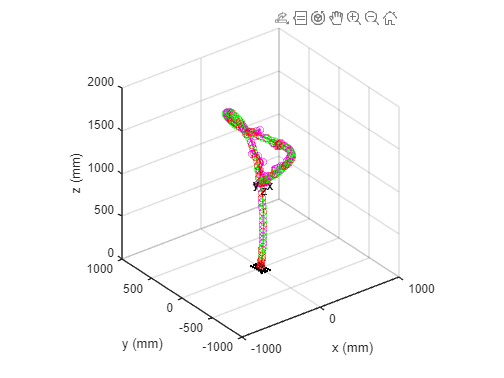

%run state estimator



%options
p3pData = p3pResult.KneipN;
p3pTimes = p3pData.time;
%timesToRun = [0, timesToRun]; %append start time



%INITIALISE STATE AND ESTIMATOR VARIABLES
%Get initial state from verification data
%(Why using second value? There's something wrong with the first. probably due to derivatives in model)
phi_0 =  cam_stateHist_GT(4,2);
theta_0 =  cam_stateHist_GT(5,2);
psi_0 = cam_stateHist_GT(6,2);
x_hist_GT = cam_stateHist_GT(:,:);
%Strip out 3D variables (only considering 2D quad for now)
x_hist_GT(7,:) = []; %remove x_dot
x_hist_GT(6,:) = []; %remove psi
%x_hist_GT(5,:) = []; %remove theta
x_hist_GT(4,:) = []; %remove phi
x_hist_GT(1,:) = []; %remove x
%initial state
x_k = x_hist_GT(:,1);


%State covariance
P_k = diag([0.001, 0.001, 0.001, 0.001, 0.001]); %Initial


%Get control input history
u_hist = imuHist(:,:); %includes measurement times in row 1
%Strip out 3D variables
u_hist(5,:) = []; %remove x_ddot
u_hist(4,:) = []; %remove gamma_dot
%u_hist(3,:) = []; %remove theta_dot
u_hist(2,:) = []; %remove phi_dot - MIGHT BE WRONG
u_k = u_hist(2:end,1);
%process noise covariance (noise space)
Q = diag([0.0001, 0.0001, 0.0001]);
%Now, what if it is really high?
Q = diag([10, 10, 10]);

%Get measurement history
pos = p3pData.Rt(2:3, 4, :); %in m
rot = p3pData.Rt(1:3, 1:3, :);
pos = reshape(pos, 2, size(pos, 3));
phi = zeros(1, size(rot, 3));
for i=1:size(rot,3)
    eul = rotm2eul(rot(:,:,i), 'XYZ');
    phi(1,i) = eul(2);
end
z_hist = [p3pTimes; pos; phi];
z_k = z_hist(2:end,1);
%and measurement covariance
W =diag([1,1,1]);
%what if this is very low?
W =diag([0.000001,0.000001,0.000001]);

% %strip out skipped frames for now
% for i=1:size(discardedFrameTimes)
%     time_I = discardedFrameTimes(i);
%     [~,closestIndex] = min(abs(cam_timeHist_GT-time_I));
%     x_hist_GT(:,closestIndex) = []; %remove x

%initialise EKF output history
stateHist_EKF = zeros(size(x_k, 1)+1, size(u_hist,2));
rtHist_ekf = zeros(3, 4, size(u_hist,2));
stateHist_EKF(2:end,1) =x_k;

%At each time step
%Which time steps?
t_delta = u_hist(1,2) - u_hist(1,1);
for i=1:(size(u_hist,2)-1)

    t_k = u_hist(1,i); %current time
    u_k = u_hist(2:end, i); %current control input
    
    %check if there is a measurement for this time
    [closestDiff, closestIndex] = min(abs(z_hist(1,:)-t_k));
    if (((closestDiff) <= (t_delta)) && (z_hist(1, closestIndex) <= t_k))
        z_k = z_hist(2:end, closestIndex);
    else
        z_k = NaN; %no new measurement
    end
    %z_k = NaN;

    %run EKF to find next state
    [x_k, P_k] = EKF_2dQuad_funcs.EKF_loop(x_k, P_k, u_k, Q, z_k, W, t_delta);
    stateHist_EKF(:,i+1) = [(t_k+t_delta); x_k];

    %RECREATE RT matrix for plotting
    rtHist_ekf(:,4,i+1)= [0; (x_k(1:2,1))]; %also convert to mm
    rtHist_ekf(:,1:3,i+1)= (eul2rotm([phi_0, x_k(3,1), psi_0], 'XYZ'));

end

%plot trajectory
% %replot for ease
% ekfFig = figure();
% ekfAx = axes('Parent', ekfFig);
plotStruct.traj.plotLines.EKF.Data = rtHist_ekf;
p3pPlotting.updateTraj(plotStruct.traj.plotLines.EKF.line, plotStruct.traj.plotLines.EKF.frameText, plotStruct.traj.plotLines.EKF.frameLines, rtHist_ekf)

drawnow